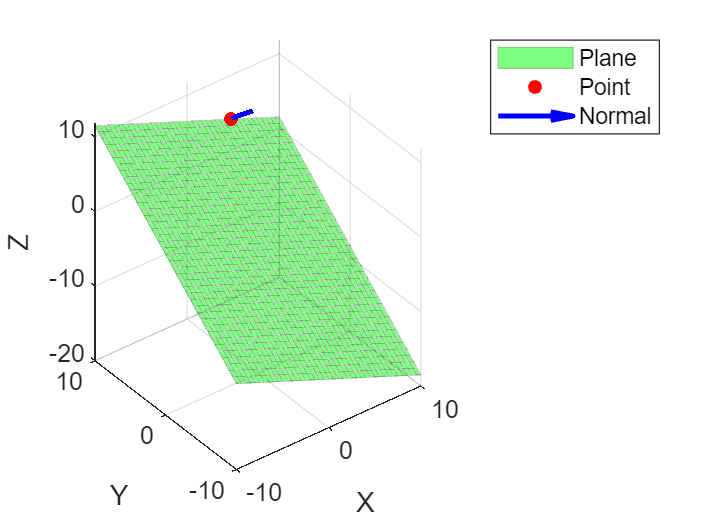

clear all,clc

point = input('Enter the point (1,5,10) divided by space: ','s');
point_values = str2num(point);

X0 = point_values(1);
Y0 = point_values(2);
Z0 = point_values(3);

if(X0~=1 || Y0~=5 || Z0~=10)
    disp('You must enter the point (1,5,10)')
    return
end

A = 1;
B = -2;
C = 2;
D = 7;

[X, Y] = meshgrid(-10:0.5:10, -10:0.5:10);
Z = (-A*X - B*Y - D) / C;

surf(X, Y, Z, 'FaceColor', 'green', 'FaceAlpha', 0.5, 'EdgeAlpha', 0.2);
hold on;
plot3(X0, Y0, Z0, 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'red');

distance = abs(A*X0 + B*Y0 + C*Z0 + D) / sqrt(A^2 + B^2 + C^2);

quiver3(X0, Y0, Z0, A, B, C, 'Color', 'blue', 'LineWidth', 2);

xlabel('X');
ylabel('Y');
zlabel('Z');
legend({'Plane', 'Point', 'Normal'});



disp("    The Initial Data ")

    The Initial Data 


disp(['X0 = ', num2str(X0), ', Y0 = ', num2str(Y0), ', Z0 = ', num2str(Z0)])

X0 = 1, Y0 = 5, Z0 = 10



syms A B C D x0 y0 z0
distance_formula = abs(A*x0 + B*y0 + C*z0 + D) / sqrt(A^2 + B^2 + C^2);

disp('D = ');

D = 


pretty(distance_formula);

|D + A x0 + B y0 + C z0|
------------------------
         2    2    2
   sqrt(A  + B  + C )




A = 1;
B = -2;
C = 2;
D = 7;
disp(['A = ', num2str(A), ', B = ', num2str(B), ', C = ', num2str(C)])

A = 1, B = -2, C = 2


disp('---------------------------------')

---------------------------------


disp(" ")

disp("            The Answer ")

            The Answer 


disp(['the distance of the point to the plane = ', num2str(distance)])

the distance of the point to the plane = 6
